Universidad de Costa Rica

Maestría de Computación e Informática

Elaborado por Ruth Campos

Fecha: 21/08/2024

Ejercicios en Clase 2:  Notas

# 2D

- Create a rotation matrix with 25 deg of rotation and name it as R

R = rotm2d(25*pi()/180)

R =     0.9063   -0.4226
    0.4226    0.9063


 2. Visualize the coordinate frame

plottform2d(R)

3. Compute the determinant

det(R)

ans = 1.0000

4. Compute RxR and its determinant 

det(R*R)

ans = 1.0000

5. Repeat steps 1 to 4 using symbolic mathematics and naming the angle as “theta” 

syms tetha real
R = rotm2d(tetha)

$$R = \left(\begin{array}{cc} \cos\left(\mathrm{tetha}\right) & -\sin\left(\mathrm{tetha}\right)\\ \sin\left(\mathrm{tetha}\right) & \cos\left(\mathrm{tetha}\right) \end{array}\right)$$

simplify(R*R)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\mathrm{tetha}\right) & -\sin\left(2\,\mathrm{tetha}\right)\\ \sin\left(2\,\mathrm{tetha}\right) & \cos\left(2\,\mathrm{tetha}\right) \end{array}\right)$$

det(R)

$$ans = {\cos\left(\mathrm{tetha}\right)}^{2}+{\sin\left(\mathrm{tetha}\right)}^{2}$$

det(R*R)

$$ans = {\cos\left(\mathrm{tetha}\right)}^{4}+2\,{\cos\left(\mathrm{tetha}\right)}^{2}\,{\sin\left(\mathrm{tetha}\right)}^{2}+{\sin\left(\mathrm{tetha}\right)}^{4}$$

6. Create two rotation matrices R1 and R2 with angles 25 and 30 deg correspondingly

R = rotm2d(25*pi()/180)

R =     0.9063   -0.4226
    0.4226    0.9063



R1 = rotm2d(25*pi()/180)

R1 =     0.9063   -0.4226
    0.4226    0.9063


R2 = rotm2d(30*pi()/180)

R2 =     0.8660   -0.5000
    0.5000    0.8660


7. Compute R12 = R1xR2 then R21 = R2xR1

 R12 = R1*R2

R12 =     0.5736   -0.8192
    0.8192    0.5736



 R21 = R2*R1

R21 =     0.5736   -0.8192
    0.8192    0.5736


8. Compute determinant of R12 and R21

 det(R12)

ans = 1.0000

 det(R21)

ans = 1.0000

9. Visualize R1, R2, R12 and R21 with different color and frame names 

hold on % grafica encima de otro gráfico
plottform2d(R1, frame="B", color='r')
plottform2d(R2, frame="C", color='g')
plottform2d(R21, frame="R21", color='r')
plottform2d(R12, frame="R12", color='r')

10. Compute Rinv = R-1 , RT = RT and Rn = R(-θ), θ = -25deg 

Rinv = inv(R)

Rinv =     0.9063    0.4226
   -0.4226    0.9063



RT = transpose(R)

RT =     0.9063    0.4226
   -0.4226    0.9063



Rn =  rotm2d(-25*pi()/180)

Rn =     0.9063    0.4226
   -0.4226    0.9063


11. Create and visualize the identity matrix I 

I = R*inv(R) % matriz identidad

I =     1.0000   -0.0000
   -0.0000    1.0000


ident = R*Rn % matriz identidad

ident =      1     0
     0     1


12. Add R, Rinv and R*Rinv to the visualization with different colors and names for the rotated coordinates. 

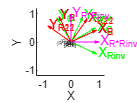


plottform2d(R, frame="R", color='r')
plottform2d(Rinv, frame="Rinv", color='g')
plottform2d(R*Rinv, frame="R*Rinv", color='magenta')

13. Clear the graph figure with clf command 

clf

14. Define a vector pA = [1 1] 

pA = [1 1]

pA =      1     1


%pA2 = [1 ; 1]

15 Visualize vector pA, I as frame A and R as frame B. How to obtain pA coordinates with respect to frame B?

hold on
plotpoint(pA, "bo",'MarkerFaceColor', 'b')
plottform2d(eye(2), frame="0", color="r");
plottform2d(R1, frame="B", color="b");
R

R =     0.9063   -0.4226
    0.4226    0.9063


pB = inv(R1)*transpose(pA)

pB =     1.3289
    0.4837


p_A = R*pB

p_A =     1.0000
    1.0000


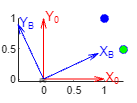

plotpoint(transpose(pB), "bo",'MarkerFaceColor', 'g')

Ejemplo del log matricial:

Nota: Nos permite obtener cual es la matriz original basandonos en skew2vec(L) o expm(L).

R =  rotm2d(25*pi()/180)
L = logm(R)
S = skew2vec(L)
expm(L)

matriz de transformacion 

rotm2d(0.3)
tformr2d(0.3)
% trvec2tform convierte un vector de traslación de 2D, a una matriz de transformación homogénea.
TA = trvec2tform([1 2])*tformr2d(deg2rad(30)) %deg2rad para cálculos de grados a radianes % matriz con translacion y rotacion
clf; axis([0 5 0 5]); hold on % new plot with both axes from 0 to 5
plottform2d(TA,frame="A",color="b");
T0 = trvec2tform([0 0]);
plottform2d(T0, frame="0",color="k");  % reference frame
TB = trvec2tform([2 1]) % matriz con translacion
plottform2d(TB,frame="B",color="r");
TAB = TA*TB
plottform2d(TAB,frame="AB",color="g");
TBA = TB*TA;
plottform2d(TBA,frame="BA",color="c");
P = [3;2];  % column vector
plotpoint(P',"ko",label="P");
inv(TA)*[P;1]
h2e(ans')
homtrans(inv(TA),P')

# 3D

tripleangleApp